clc;close all; clear all;

tic
t = [0 .3 .8 1.1 1.6 2.3]'

t =          0
    0.3000
    0.8000
    1.1000
    1.6000
    2.3000


y = [.82 .72 .63 .60 .55 .50]'

y =     0.8200
    0.7200
    0.6300
    0.6000
    0.5500
    0.5000


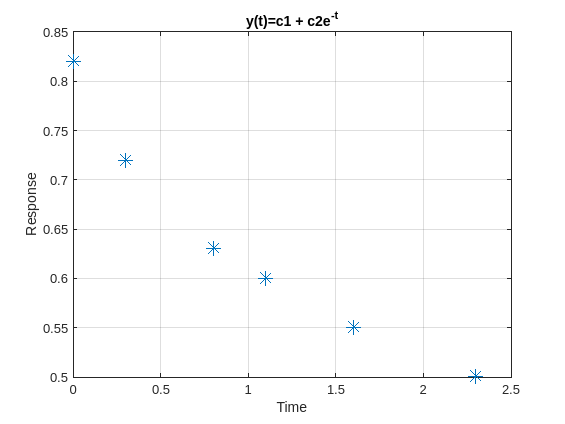

plot(t, y, '*', 'MarkerSize', 10)
grid on
xlabel('Time')
ylabel('Response')
hold on
title('y(t)=c1 + c2e^{-t}')

E = [ones(size(t)) exp(-t)]

E =     1.0000    1.0000
    1.0000    0.7408
    1.0000    0.4493
    1.0000    0.3329
    1.0000    0.2019
    1.0000    0.1003


c = E\y

c =     0.4760
    0.3413


tf = (0:0.1:2.5)';
Ef = [ones(size(tf)) exp(-tf)];
yhat = Ef * c;
plot(tf, yhat)
p = optimproblem;
x = optimvar('x', 2);
p.ObjectiveSense = 'minimize';
p.Objective = sum((E*x-y).^2);
p.Constraints.intercept = x(1) + x(2) == 0.82

p =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 1 OptimizationVariable
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 1 OptimizationConstraint

  See problem formulation with show.


sol = solve(p)

Solving problem using lsqlin.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


sol = struct with fields:
    x: [2×1 double]


cNew = sol.x

cNew =     0.4749
    0.3451


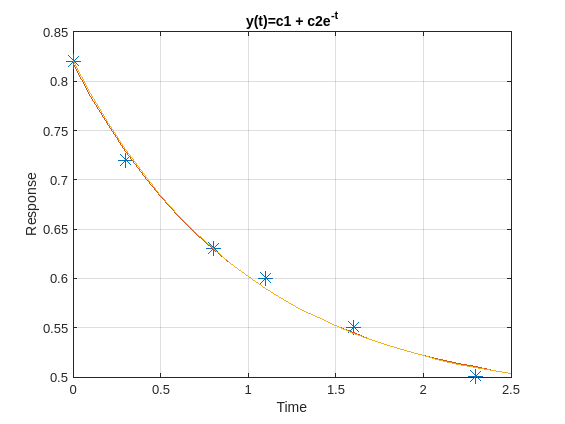

yhatc = Ef*cNew;
plot(tf, yhatc)

toc

Elapsed time is 3.444684 seconds.
